## **Klasszikus ortogonális polinomok**

#### **Csebisev elsőfajú polinom**


$$[-1; 1], \quad w(x) =\frac{1}{\sqrt{1-x^2}},\\
T_0(x) = 1, \quad T_1(x) = x,\\
T_{n+1}(x) =2x \cdot T_n(x) -T_{n-1}(x) \quad (n = 1, 2, . . .).$$



$$T_2(x) = 2x \cdot T_1(x) -T_0(x) = 2x^2-1
$$



$$T_3(x) =2 x \cdot T_2(x) - T_1(x) = 4x^3-2x-x
=4x^3-3x
$$


N=5;
T=zeros(N+1,N+1);
Tef=zeros(N+1,N+1);
T(1,N+1)=1;
T(2,N)=1;

for k=2:N
    T(k+1,1:N+1)=2*[T(k,2:N+1),0]-T(k-1,1:N+1);
end
T

T =      0     0     0     0     0     1
     0     0     0     0     1     0
     0     0     0     2     0    -1
     0     0     4     0    -3     0
     0     8     0    -8     0     1
    16     0   -20     0     5     0



for k=0:N
    Tef(k+1,:)=T(k+1,:)/T(k+1,N-k+1);
end
Tef

Tef =          0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0
         0         0         0    1.0000         0   -0.5000
         0         0    1.0000         0   -0.7500         0
         0    1.0000         0   -1.0000         0    0.1250
    1.0000         0   -1.2500         0    0.3125         0


Rajzoljuk ki az egy főegyütthatós Csebisev elsőfajú polinomokat!

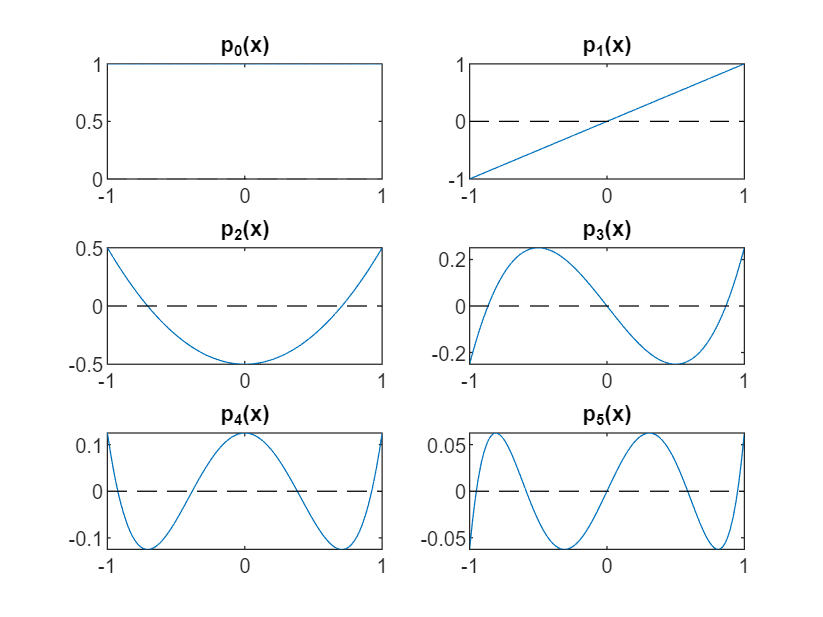

xx=linspace(-1,1,100);

for k=1:6
    subplot(3,2,k)
    pk=Tef(k,:);
    ppk=polyval(pk,xx);
    plot(xx,ppk,'-',xx,0*xx,'k--');
    title(sprintf('p_%d(x)',k-1));
end